# **EXPERIMENT 3**

#### **NAME: RAHIL SHARMA**

**PRN: 18070123062**

**BATCH: 2018-2022**

**DIVISION: EA-3**

**AIM: To study the concept of QPSK**

**Software Used: MATLAB**

**Theory: **

QPSK: The Quadrature Phase Shift Keying QPSKQPSK is a variation of BPSK, and it is also a Double Side Band Suppressed Carrier DSBSCDSBSC modulation scheme, which sends two bits of digital information at a time, called as bigits.Instead of the conversion of digital bits into a series of digital stream, it converts them into bit pairs. This decreases the data bit rate to half, which allows space for the other users. 

Quadrature Phase Shift Keying (**QPSK**) is a form of phase **modulation** technique, in which two information bits (combined as one symbol) are **modulated** at once, selecting one of the four possible carrier phase shift states.

**Code and Output:**

clc
clear all;
close all;
cvx = input('Enter length of Random Bit Sequence: '); %24
d = round(rand(1,cvx))

d =      1     1     0     1     1     0     0     1


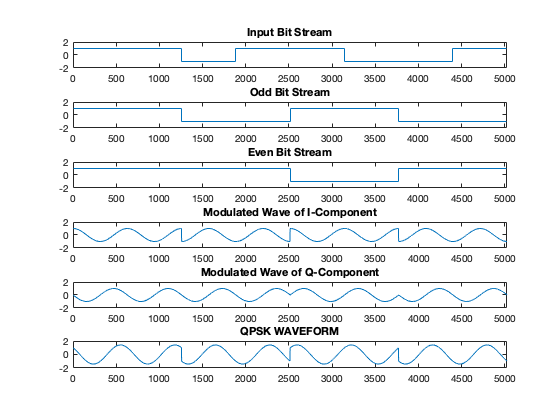

l=cvx;
x=0:0.01:l*2*pi;
cc=cos(x);
cs=cos(x+pi/2);
k=length(cc);
k1=k/l;
for i=1:l
    if(d(i)==0)
        d(i)=-1;
        i=i+1;
    end
end

i=1;
j=1;
while (i<l) && (j<l)
    dd1(j)=d(i);
    dd1(j+1)=d(i);
    dd2(j)=d(i+1);
    dd2(j+1)=d(i+1);
    j=j+2;
    i=i+2;
    
end
t=1;
for i=1:l
    for j=1:k1
        dd(t)=d(i);
        d1(t)=dd1(i);
        d2(t)=dd2(i);
        t=t+1;
        j=j+1;
        
    end
    i=i+1;
end

subplot(6,1,1);
stairs(dd);
axis([0 t -2 2]);
title("Input Bit Stream");
subplot(6,1,2);
stairs(d1);
axis([0 t -2 2]);
title("Odd Bit Stream");
subplot(6,1,3);
stairs(d2);
axis([0 t -2 2]);
title("Even Bit Stream");

len=length(d1);
if(k<len)
    len=k;
end

for i=1:len
    qcc(i)=cc(i)*d1(i);
    qcs(i)=cs(i)*d2(i);
    i=i+1;
end

subplot(6,1,4);
plot(qcc);
axis([0 len -2 2]);
title('Modulated Wave of I-Component');
subplot(6,1,5);
plot(qcs);
axis([0 len -2 2]);
title('Modulated Wave of Q-Component');

qp=qcc+qcs;
subplot(6,1,6);
plot(qp);
axis([0 len -2 2]);
title('QPSK WAVEFORM');

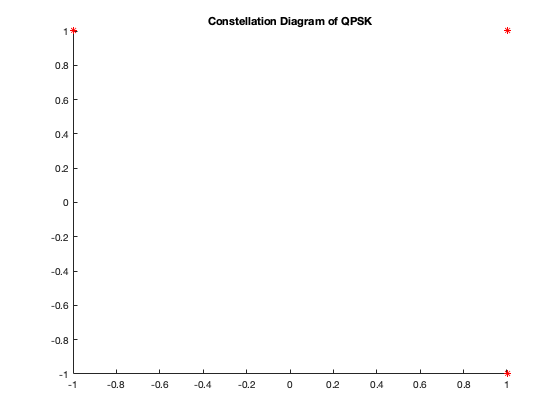

figure, scatter(dd1,dd2,40,'*r');
title('Constellation Diagram of QPSK');

CONSLUSION: From this experiment, I have learnt the concept of QPSK.